# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 20.01.2023, 18:00

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox. `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

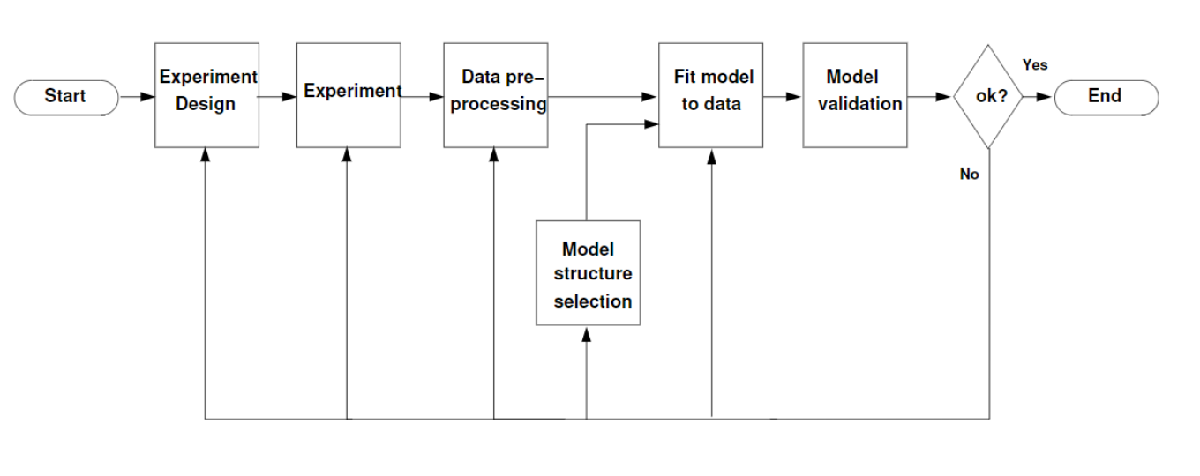

## Part 0: Setup

Please insert your names and student numbers below.

Name: Leon Khler

Student Number: 4834186

Name: Zekai Chen

Student Number: 5705762

% Clear workspace
clearvars; clc; close all;
warning("off")

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 4834186;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to

Determine a suitable sampling frequency and motivate your answer.

*Answer**: *

*The basic principle for choosing a sampling frequency is to reflect the dynamic of the system. We chose three frequencies, 1Hz, 10Hz, and 100Hz which has the color blue, red, and orange. We simulated the system by giving it a step input. From the figure, we were able to tell that the lowest frequency (1Hz) cuts out the oscillation which fails to reflect the dynamics of the system. Thus, compared to the three frequencies selected, 10 Hz is more than enough.*

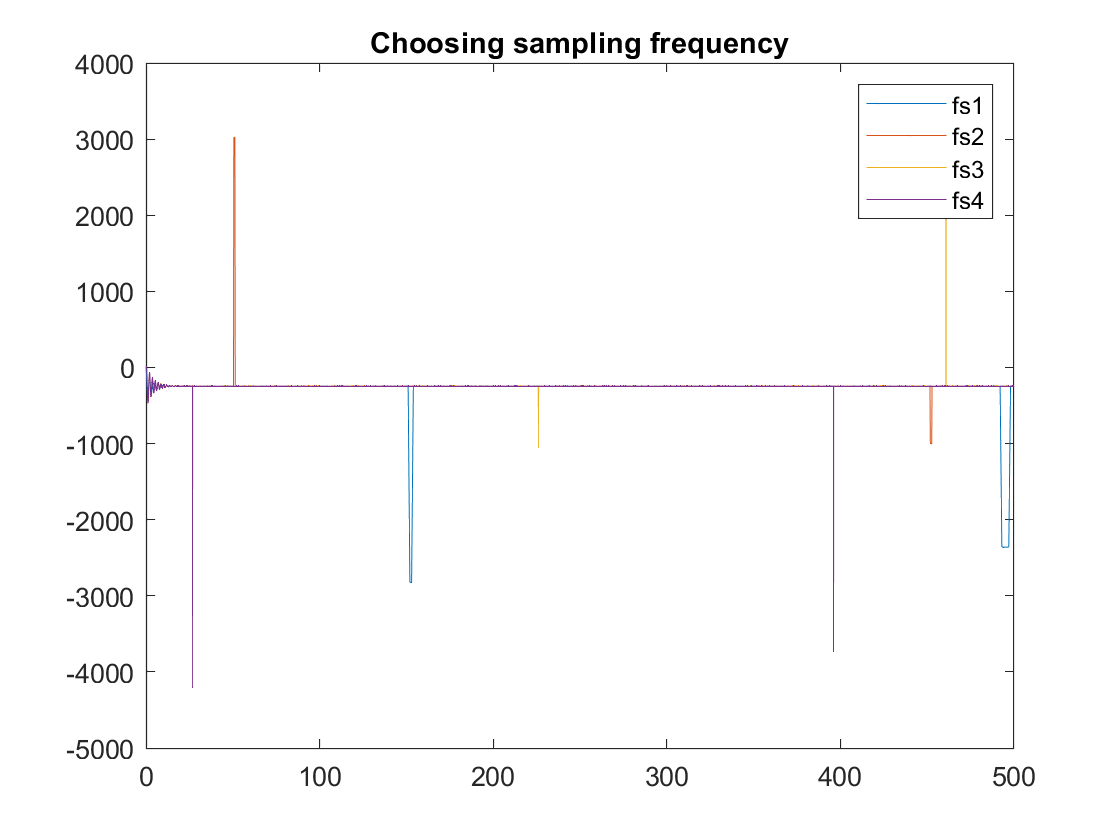

% Step input --- to check the time delay
scaling_factor = 100;
end_time = 500;
spike_tolerance= 5;
fs = 1;
fs2 = 10;        
fs3 = 50;
fs4 = 100;
t = 0:(1/fs):end_time;
t2 = 0:(1/fs2):end_time;
t3 = 0:(1/fs3):end_time;
t4 = 0:(1/fs4):end_time;
input = scaling_factor*ones(1, length(t));                
input2 = scaling_factor*ones(1, length(t2)); 
input3 = scaling_factor*ones(1, length(t3));
input4 = scaling_factor*ones(1, length(t4));
y = exciteSystem(STUDENTID,input,fs);
y2 = exciteSystem(STUDENTID,input2,fs2);
y3 = exciteSystem(STUDENTID,input3,fs3);
y4 = exciteSystem(STUDENTID,input4,fs4);

figure()
plot(t, y)
hold on;
plot(t2, y2)
plot(t3, y3)
plot(t4, y4)
hold off
legend("fs1", "fs2", "fs3", "fs4")
title("Choosing sampling frequency")

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**:*

*Since the input signal is a step, which is 1 at t=0, all u(v) for v >= 0 are 1. Thus, according to definition 10.1, all entries are equal to 1, rendering only one row (i.e. no second row can be constructed independent from the first one). Thus, the order is 1.*

%YOUR CODE HERE

Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**:*

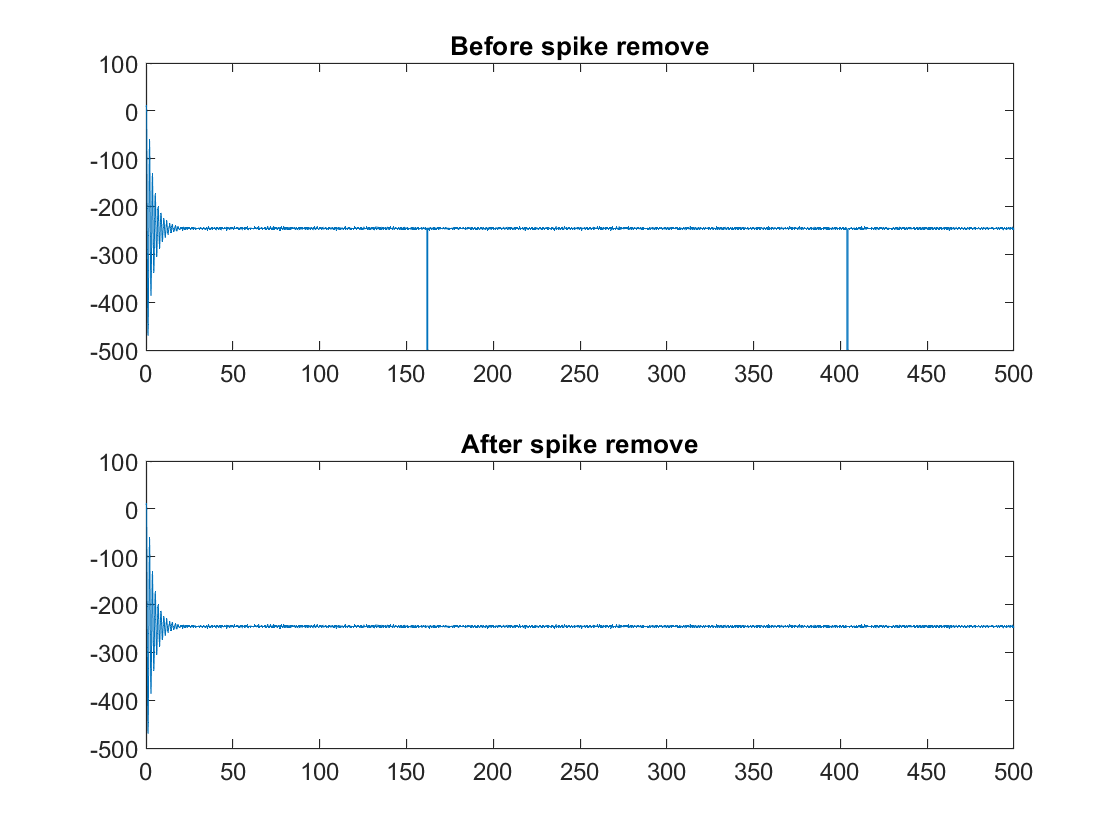

%YOUR CODE HERE
y_spiky = y2;
y_clean = removespikes(y_spiky, spike_tolerance);

figure()
subplot(2, 1, 1);
plot(t2, y_spiky)
title("Before spike remove");
ylim([-500, 100]);

subplot(2, 1, 2);
plot(t2, y_clean);
title("After spike remove");
ylim([-500, 100]);

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**:*

*From the first part's plot, it can be seen that from the step at t equals 0 as our input, our system starts moving after 0.4 second. Thus, the time delay is approcimately 0.4 second. Noted that in order to show the time delay, we adopted the sampling frequency of 100 Hz instead of original 10 Hz. To eleminiate the time-delay, we moved the signal 0.4 second to the left. Noted that we only plotted 2 seconds, but the shift operation also effects later part.*

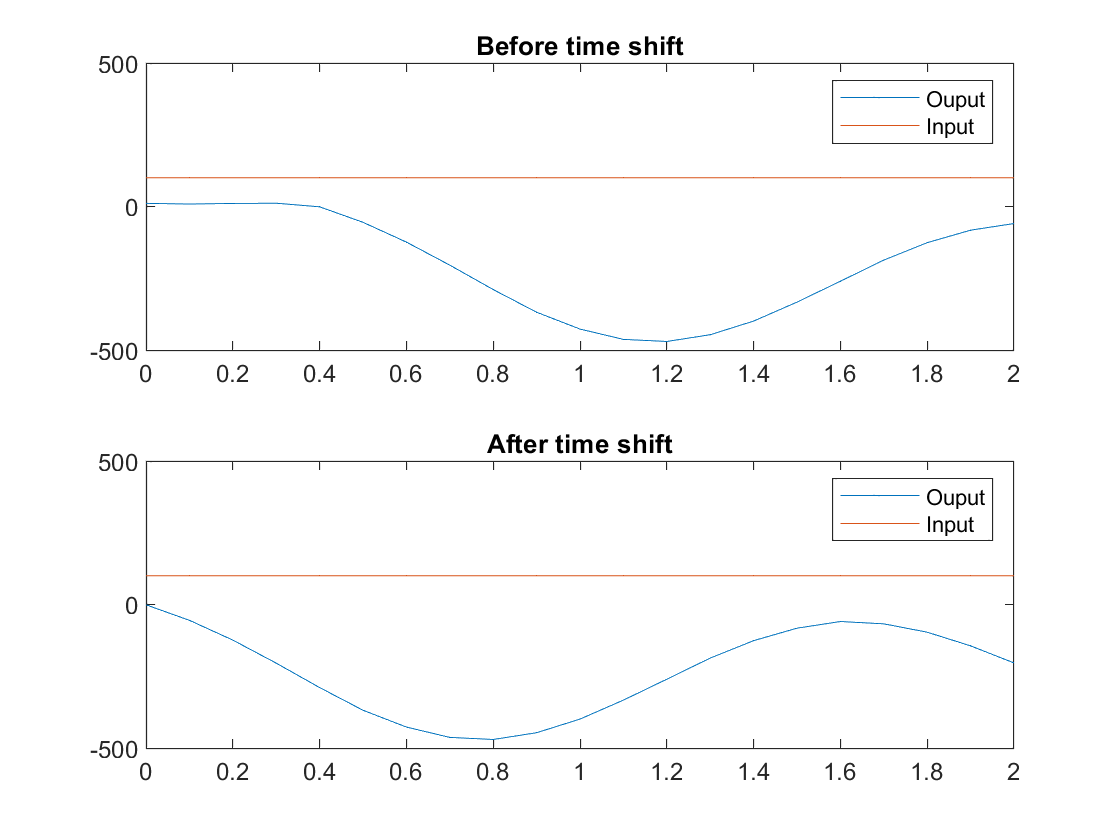

%YOUR CODE HERE
time_shift = 0.4;

figure()
subplot(2, 1, 1);
plot(t2, y2);
hold on;
title("Before time shift");
plot(t2, input2);
hold off;
xlim([0, 2]);
ylim([-500, 500]);
legend("Ouput", "Input")

subplot(2, 1, 2);
y2 = timeshift(y2, time_shift, fs2);
plot(t2, y2);
hold on;
title("After time shift");
plot(t2, input2);
hold off;
xlim([0, 2]);
ylim([-500, 500]);
legend("Ouput", "Input")

Remove the DC offset from the output (if any).

*Answer**:*

*The DC offset is the constant bias which shifts the signal up or down. For a given input the response is offset from 0 by both the system gain and the bias. Since we only want the bias, we need to excite the system with a zero mean signal, e.g. a sin wave or just take the autonomous response, i.e. a zero input. Then, the spikes have to be removed again. The mean of the resulting signal is the DC offset or bias.*

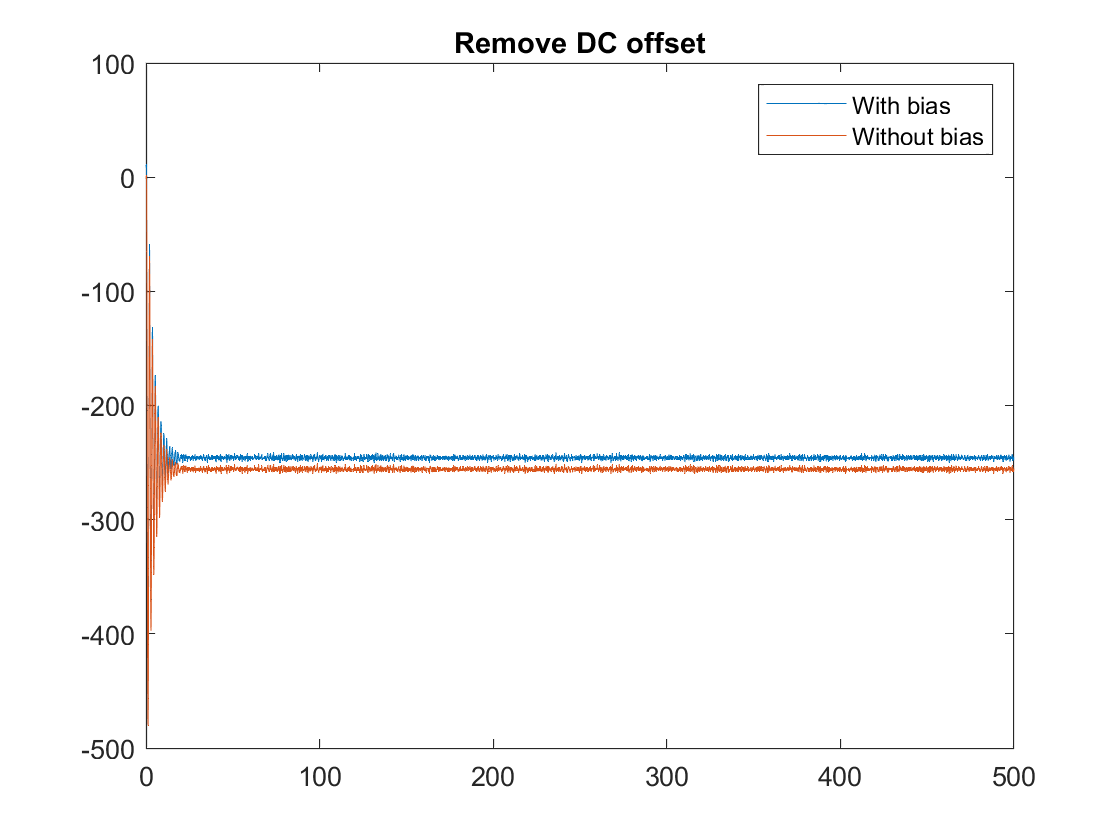

%YOUR CODE HERE
%input_zm = sin(t2);                                % input with zero mean
input_zm = zeros(1, length(t2));                    % input with zero mean
output = exciteSystem(STUDENTID, input_zm, 10);
output_zm_clean = removespikes(output, spike_tolerance);
bias = mean(output_zm_clean);
new_output = RemoveBias(y_clean, bias);

figure()
plot(t2, y_clean);
hold on;
plot(t2, new_output)
hold off;
legend("With bias", "Without bias")
title("Remove DC offset");

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions.

*Answer**:*

*we conducted an experiment based on the superposition principle, from which we can conlcude that the system is (approximately) a linear system given that the combined output equals to the outcome of a combined input.*

%YOUR CODE HERE
initial_index = 80;
steady_value1 = mean(new_output(initial_index:end));

%% Adopt superposition principle
% scaling
scaling_factor2 = 2;
y_scale2 = exciteSystem(STUDENTID,scaling_factor2*input2,fs2);
y_clean2 = removespikes(y_scale2, spike_tolerance);
new_output2 = y_clean2 - bias;
steady_value2 = mean(new_output2(initial_index:end));
ratio = steady_value2/steady_value1

ratio = 2.0001

% combination
step_output = steady_value1;
sin_input = sin(t2);
sin_output = exciteSystem(STUDENTID,sin_input,fs2);
sin_output_clean = removespikes(sin_output, spike_tolerance) - bias;
sin_output = mean(sin_output_clean(initial_index:end));
combined_output = sin_output + step_output

combined_output = -255.8243

combined_output_compare = exciteSystem(STUDENTID,sin_input+input2,fs2);
combined_output_compare_clean = removespikes(combined_output_compare, spike_tolerance) - bias;
combined_output_compare_ss = mean(combined_output_compare_clean(initial_index:end))

combined_output_compare_ss = -255.8517

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**:*

*We use the step input and the clean version of output as identificaiton input and output. Correspondingly, frequency sweep signal was adopted as validation input, and the clean version of its output was used as validation output.*

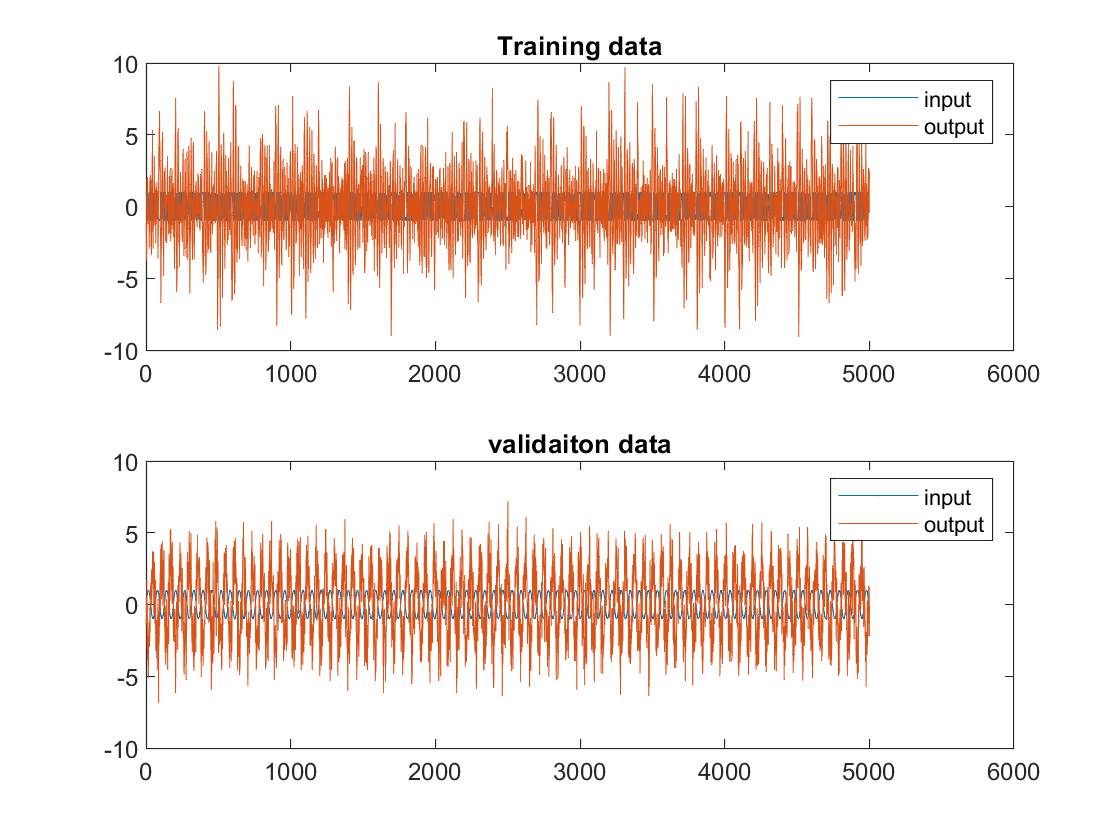

%YOUR CODE HERE
fs_final = fs2;
t_final = t2;

% Validation: sin;  Identification: chirp
validation_input = sin(t2);
validation_output_draft = exciteSystem(STUDENTID,validation_input,fs2);
validation_output = RemoveBias(timeshift(removespikes(validation_output_draft, spike_tolerance), ...
    time_shift, fs_final), bias);

identification_input = chirp(t2, 1, t2(end), 500);
identification_output_draft = exciteSystem(STUDENTID,identification_input,fs2);
identification_output = RemoveBias(timeshift(removespikes(identification_output_draft, spike_tolerance), ...
    time_shift, fs_final), bias);

identification_input = identification_input';
identification_output = identification_output';
validation_input = validation_input';
validation_output = validation_output';

% Visualizaion
figure();
subplot(2, 1, 1)
plot(identification_input)
hold on;
plot(identification_output);
hold off;
legend("input", "output")
title("Training data")

subplot(2, 1, 2)
plot(validation_input);
hold on;
plot(validation_output);
hold off;
legend("input", "output")
title("validaiton data")

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**:*

*From the singular value plot, we are able to see that there are 6 points isolated from the original plot. Thus, we chose the order of the system to be 6. Noted that in order to achieve a better performance, we might increase the order of the system to some extent while training.*

%YOUR CODE HERE
s = 50;   % for subspace identification

% vector_shape = N * 1;
U_hankel = create_hankel(identification_input, s);      
size(U_hankel)

ans =          100        4902


rank(U_hankel)          % full rank

ans = 100

Y_hankel = create_hankel(identification_output, s);             
size(Y_hankel)

ans =          100        4902


rank(Y_hankel)          % full rank

ans = 100

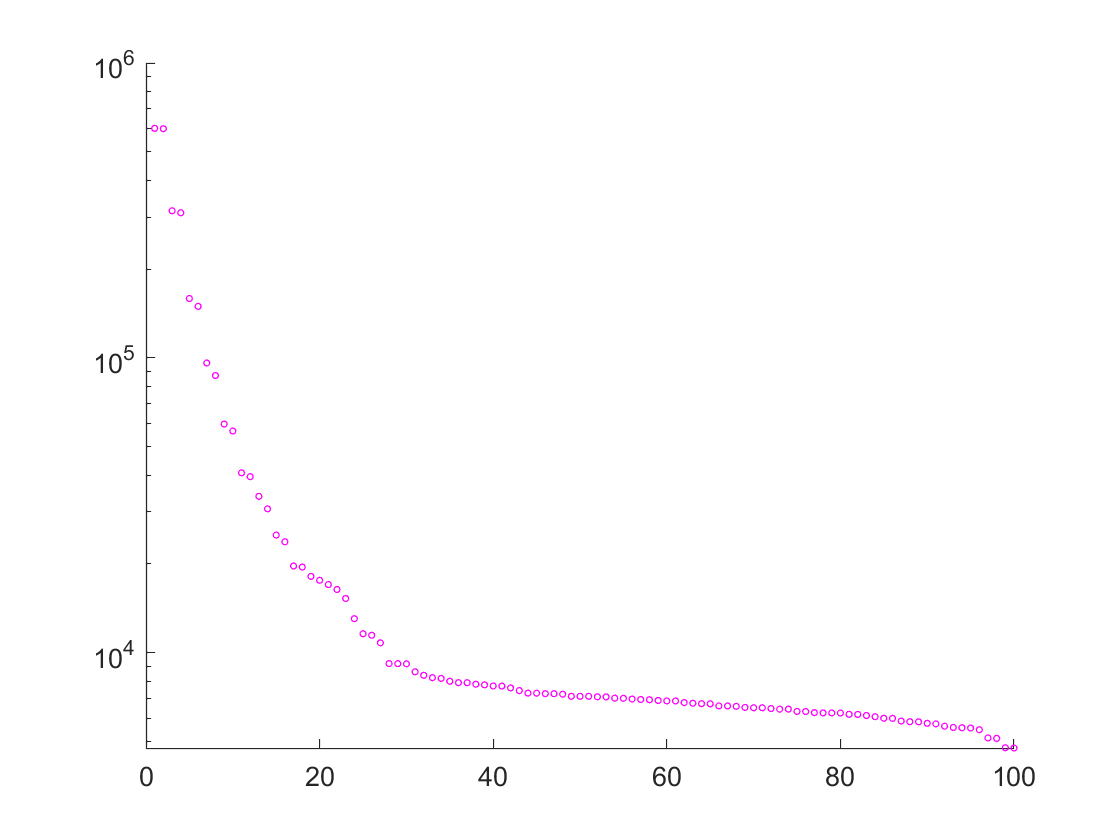

[U_SVD, S_SVD, V_SVD] = svd(Y_hankel*Y_hankel');
figure()
S_diag_el = diag(S_SVD);
scatter(1:size(S_diag_el),S_diag_el,5,"magenta")
set(gca,'yscale', 'log')

Identify the model. You are free to choose the identification method.

*Answer**:*

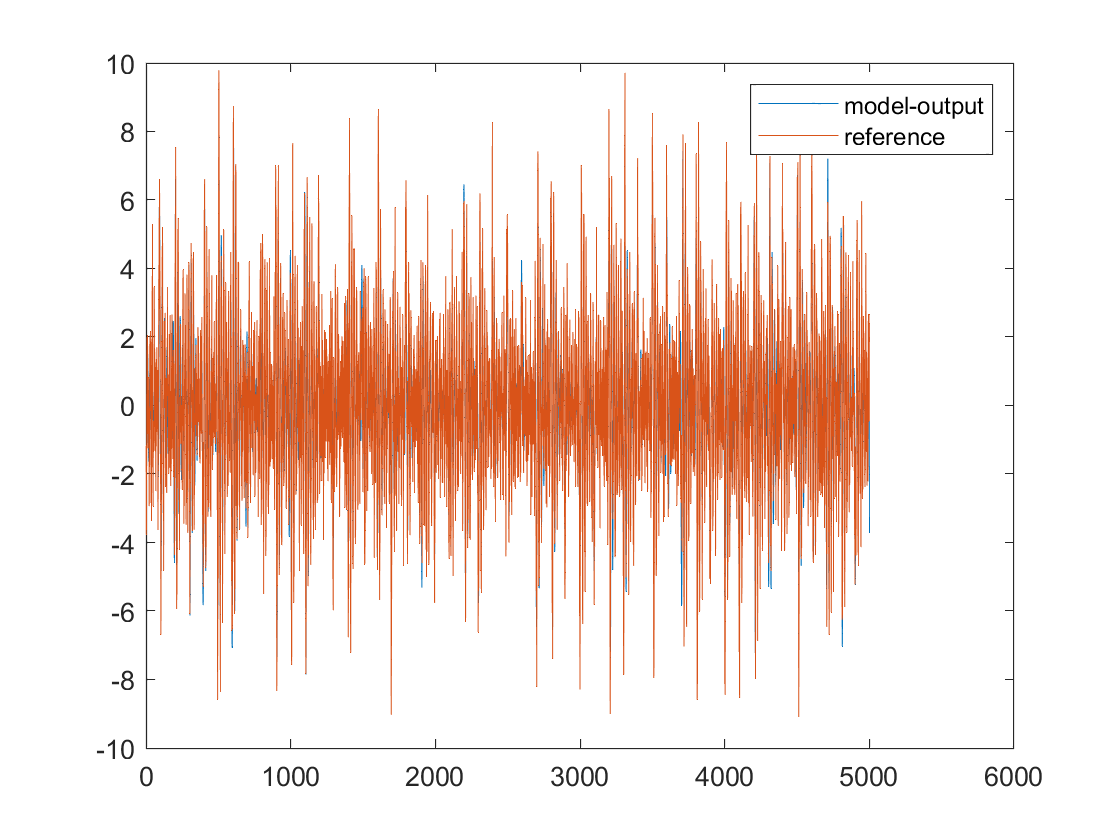

%YOUR CODE HERE
n = 2;
[A,B,C,D,x0] = pomoesp(identification_input, identification_output, s, n);
yhat_po_moesp_train = simsystem(A,B,C,D,x0,identification_input);

figure()
plot(yhat_po_moesp_train);
hold on;
plot(identification_output);
hold off;
legend('model-output', 'reference')

## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

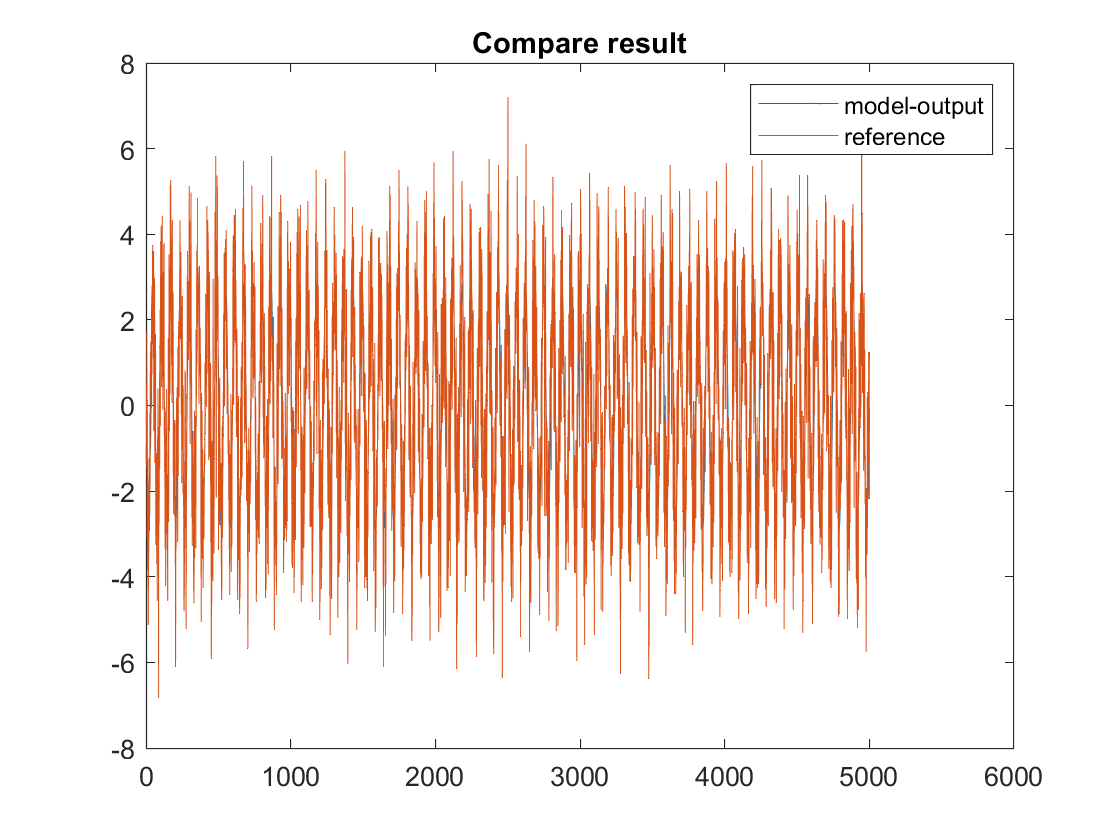

%YOUR CODE HERE
yhat_validation = simsystem(A,B,C,D,x0,validation_input);

figure()
plot(yhat_validation);
hold on;
plot(validation_output);
hold off;
legend('model-output', 'reference')
title("Compare result")

VAF_value = VAF(validation_output, yhat_validation)

VAF_value = 66.0472

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

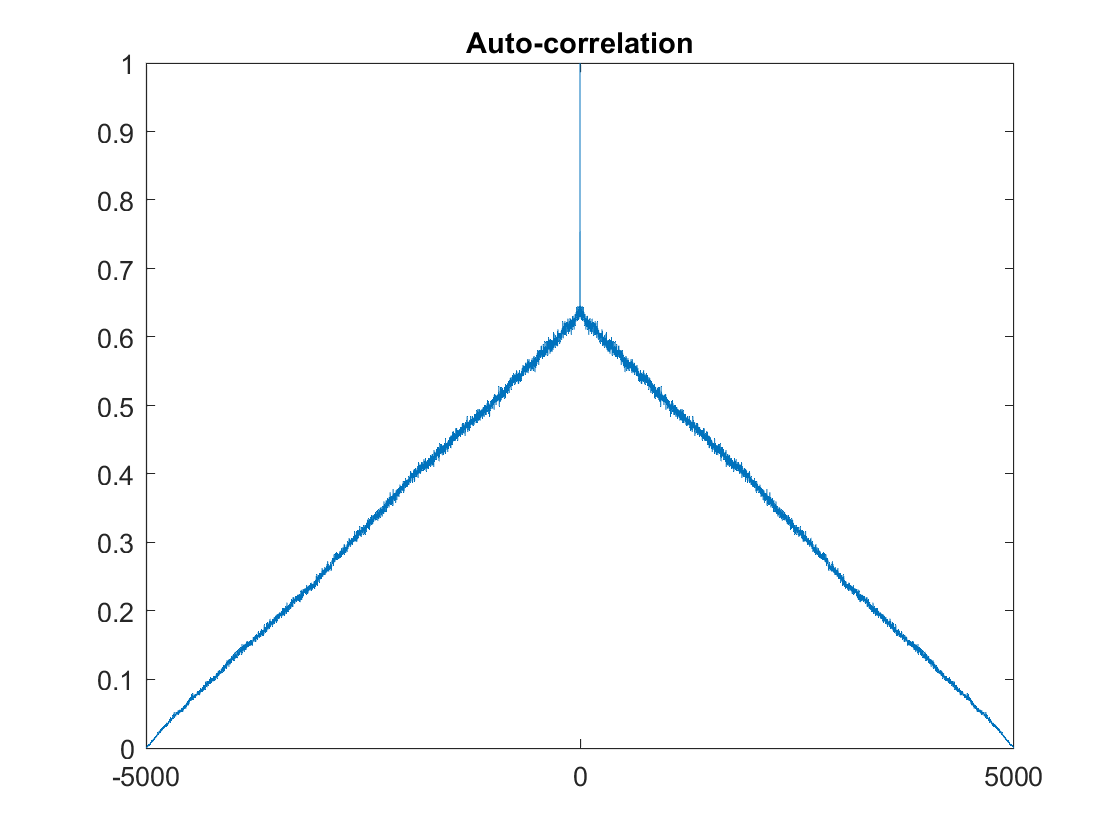

res = abs(yhat_validation - validation_output);
[auto, lags] = xcorr(res, res', 'normalized');
figure();
plot(lags, auto);
title("Auto-correlation");

Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

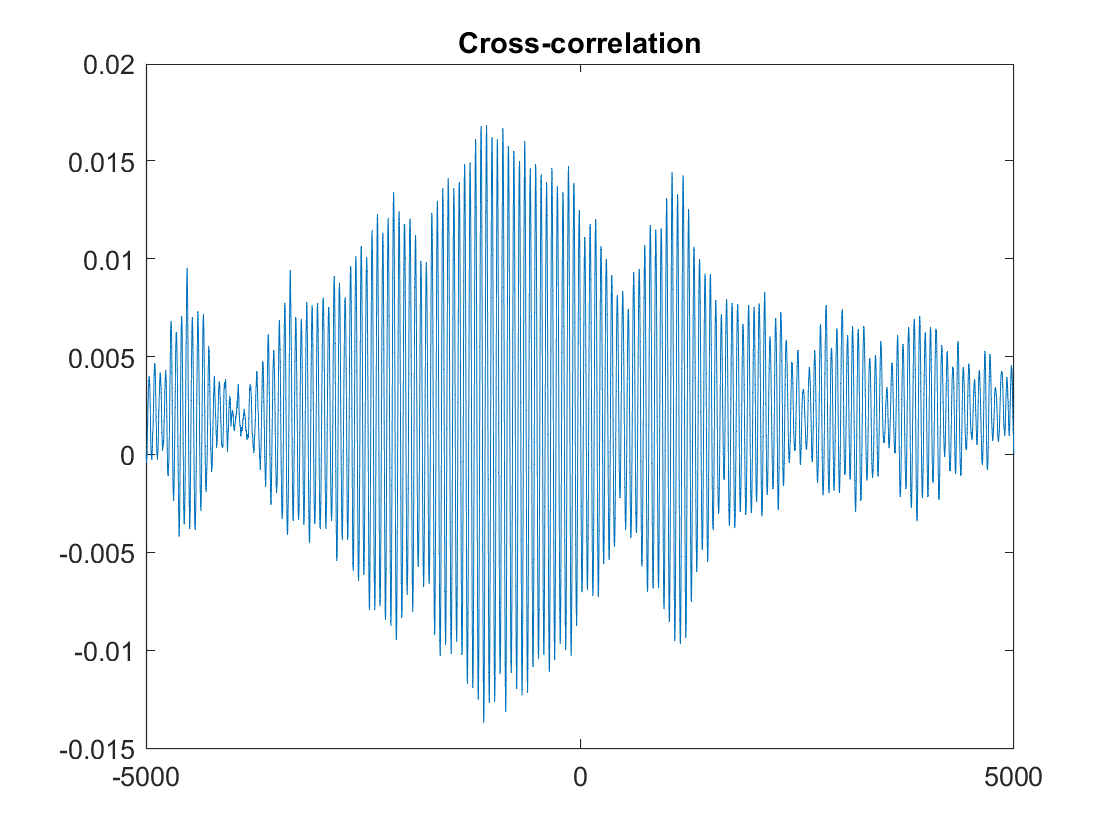

[cross, lag2] = xcorr(res, validation_input, "coeff");
figure();
plot(lag2, cross);
title("Cross-correlation");

**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

## Functions

Implement your functions in this section

### Prediction Error Methods

Implement your PEM functions below 

%YOUR CODE HERE

### Subspace ID Methods

Implement your Subspace ID functions below 

function y = timeshift(y_original, t_s, f_s)
y = y_original;
shift_index = ceil(t_s*f_s);
for i = 1: (length(y_original)-shift_index)
    y(i) = y_original(i+shift_index);
end
end

function y = RemoveBias(y_original, b)
y = y_original - b;
end

function y = simsystem(A,B,C,D,x0,u)
sys_po_moesp = ss(A,B,C,D,1);
y = lsim(sys_po_moesp,u,[],x0);
end

function [A_h] = create_hankel(a, s)
A_h = hankel(a(1:2*s), a(2*s:end));
end

function [y, varargout] = removespikes(yin, tol)
    aver = mean(yin);
    stndd = std(yin);

    maxy = aver + stndd*tol;
    miny = aver - stndd*tol;

    x=1:length(yin);
    spikes=[];
    for i=1:length(yin)
        if yin(i)>maxy || yin(i)<miny
            spikes = [spikes,i];
        end
    end
    y=yin;
    y(spikes)=[];
    x(spikes)=[];
    y=interp1(x,y,1:length(yin),"linear","extrap");

    varargout{1}=aver;
    varargout{2}=maxy;
    varargout{3}=miny;
end


function [A,B,C,D,x0]=pomoesp(u_small,y_small,s,n)
U_hankel = create_hankel(u_small,s);        % rank = 100
Y_hankel = create_hankel(y_small,s);        % rank = 100
LQ_vector = [U_hankel(s+1:end,:)
                U_hankel(1:s,:)
                Y_hankel];

[Q, R] = qr(LQ_vector');

Q = Q';
R = R';

L_32 = R(3*s+1:end,s+1:3*s);

%n = varargin{1};

[U, S, V] = svd(L_32);

C = U(1,1:n);
A = U(1:s-1,1:n)\U(2:s,1:n);

N = size(y_small,1);
Phi = zeros(N,2*n+1);
for k =1:n
    dB = zeros(n,1);
    dB(k,1)=1;
    sys1 = ss(A,dB,C,0,1);
    Phi(:,k+n)=lsim(sys1,u_small);
end
for j = 1:N
    Phi(j,1:n) = C*A^(j-1);
end

Phi(:,k+4) = u_small;
BD = Phi\y_small;

%unstack vector
x0 = BD(1:n);
B  = BD(n+1:2*n);
D  = BD(end); 
end

function vaf = VAF(y, yhat)
vaf = (1-(var(y-yhat))/var(y))*100;
end